clear;close;clc;

## This file acts to test the functionality of rk4.m's Runga-Kutta Approximation

## Functions:

The function dt acts as our test differential equation, modeling Fig B1

## Approximation

Variables for our RK4 are as below:

ti = 0; % t initial
tf = 24; % t final
npts = 240; % # of steps for our estimation
y0 = 50; % Starting T
f = @dt; % Reference equation

% Our unsolved differential equation
function T = dt(to,To)
    T = 75/4 - To/4;
end

% Calls rk4.m and stores it in a matrix

[test,Test] = rk4(ti,tf,npts,y0,f);

## Real Value Calculation

Variable

ttrue = linspace(ti,tf,npts+1);
Ttrue = zeros(1,npts+1); 

% Real Value Equation:
function T = dtrue(t)
    T = 75 - 25 * (exp(1)^(-t/4));
end

% Real Value Graph
for i = 1 : npts+1
    Ttrue(i) = dtrue(ttrue(i));
end

## Calculation of error over time

Error Matrix

Err = zeros(1, npts+1);

% Error Equation
for i = 1 : npts+1
    Err(i) = 100 * (Ttrue(i) - Test(i))/Ttrue(i);
end

## Plotting

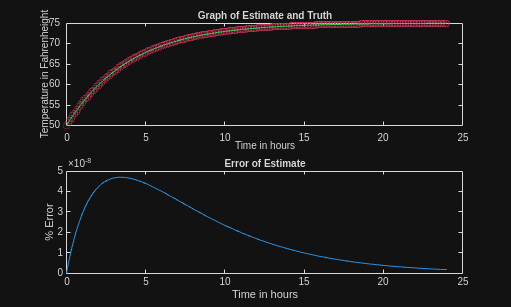

figure
tiledlayout
nexttile
% T of t graph
pest = plot(test,Test,"-o");
fontsize(15,"points")
title("Graph of Estimate and Truth","FontSize",15)
xlabel("Time in hours")
ylabel("Temperature in Fahrenheight")
pest.Color = '#cc2f59';
pest.MarkerSize = 10;
hold on;
ptrue=plot(ttrue,Ttrue);
ptrue.Color = '#2fcc4e';
hold off
nexttile
% Error Graph
perror = plot(test, Err);
fontsize(15,"points")
title("Error of Estimate","FontSize",15)
xlabel("Time in hours")
ylabel("% Error")